## Dengue mosquito detection 

Dengue fever, caused by the dengue virus and transmitted primarily by the Aedes mosquito species, poses a significant global health challenge. The disease manifests in various forms, ranging from asymptomatic cases to severe and potentially fatal outcomes. Early detection and intervention are crucial in controlling the spread of dengue fever and mitigating its impact on affected communities.

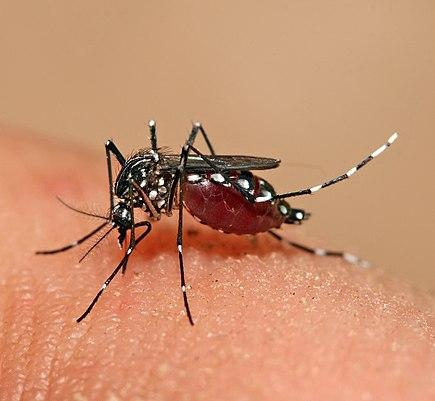

                                                        *src:https://en.wikipedia.org/wiki/Dengue_fever*

### 01.Read the audio file in the time domain 

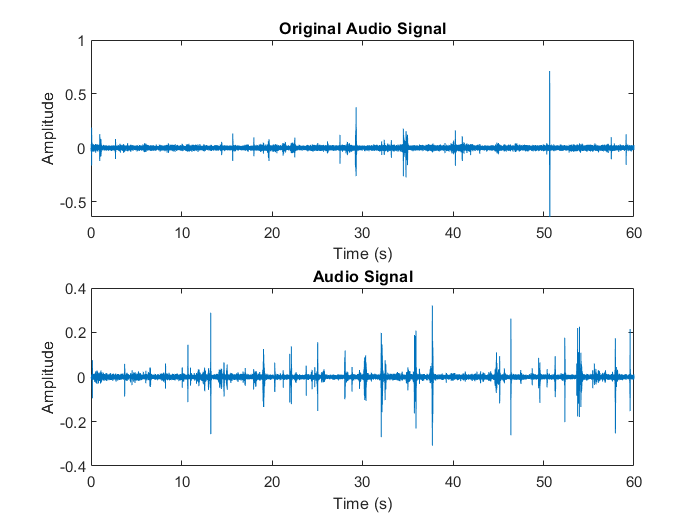

% Full path to the audio file
full_path = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\Voice0135 AEGY10130f.wav';

% Load audio file
[y, Fs] = audioread(full_path);

% Calculate the time axis
t = (0:length(y)-1) / Fs;

% Plot the time-domain waveform
plot(t, y);
title('Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

### 02.Filter the sound to reduce the noice of the signal

apply filter and  it's important to balance noise reduction with preserving the desired audio content.

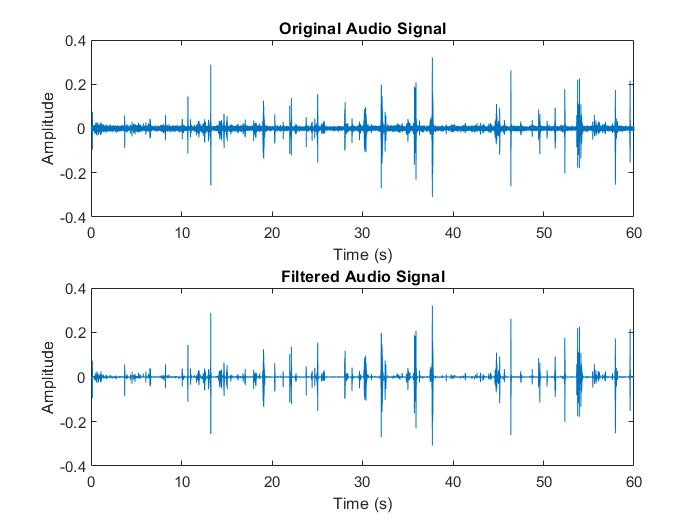


y_filtered = wiener2(y, [3 3]);

% Plot the original and filtered signals
t = (0:length(y)-1) / Fs;
subplot(2,1,1);
plot(t, y);
title('Original Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, y_filtered);
title('Filtered Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

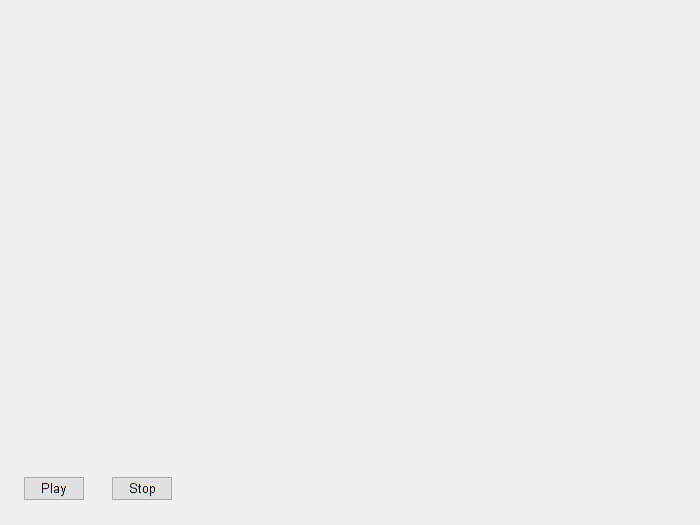


% Create audioplayer object
player = audioplayer(y_filtered, Fs);

% Create figure and buttons
fig = figure;
playButton = uicontrol('Style', 'pushbutton', 'String', 'Play', 'Position', [20 20 50 20], 'Callback', {@playCallback, player});
stopButton = uicontrol('Style', 'pushbutton', 'String', 'Stop', 'Position', [90 20 50 20], 'Callback', {@stopCallback, player});

### 03.Make the frquency spectrum of the audio

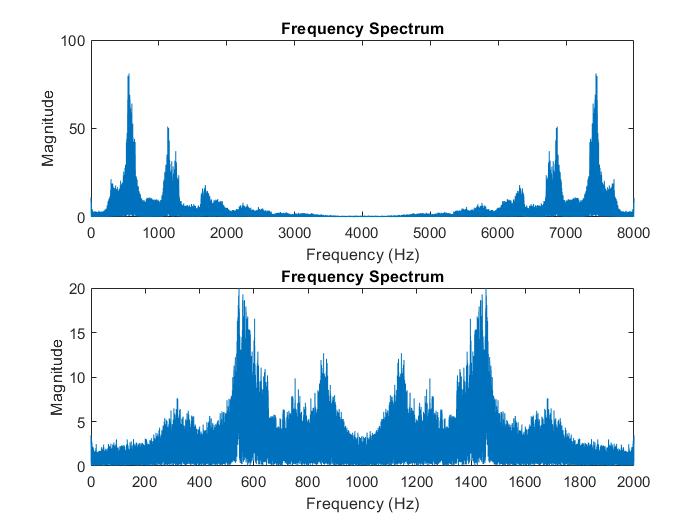

% Frequency spectrum plot
subplot(2,1,1);
N = length(y_filtered);
Y = fft(y_filtered);
f = (0:N-1) * Fs / N;
plot(f, abs(Y));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 Fs/2]);

downsample_factor = 4; % Adjust as needed
y_downsampled = downsample(y_filtered, downsample_factor);
Fs_downsampled = Fs / downsample_factor;

% Frequency spectrum plot
subplot(2,1,2);
N = length(y_downsampled);
Y = fft(y_downsampled);
f = (0:N-1) * Fs_downsampled / N;
plot(f, abs(Y));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 Fs_downsampled/2]);

subplot(2,1,1)
xlim([0 8000])
ylim([0 100])
subplot(2,1,2)
xlim([0 2000])
ylim([0.0 20.0])

subplot(2,1,1)
xlim([0 8000])
ylim([0 100])
subplot(2,1,2)
xlim([0 2000])
ylim([0.0 20.0])

### 04.Get another audio clip and plot the frequency spectrum

sampling rate is 44kHz

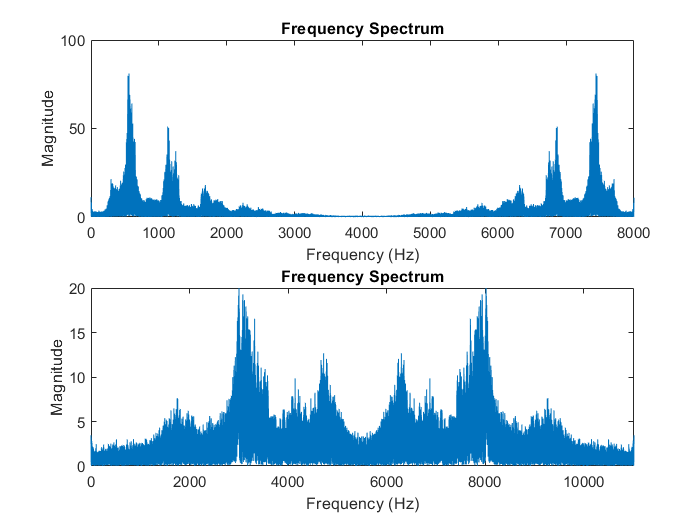

% Full path to the audio file
full_path = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\11-16-2016-111457 10130f.wav';

% Load audio file
[y, Fs] = audioread(full_path);

% Calculate the time axis
t = (0:length(y)-1) / Fs;

% Frequency spectrum plot
subplot(2,1,1);
N = length(y_filtered);
Y = fft(y_filtered);
f = (0:N-1) * 8000 / N;
plot(f, abs(Y));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 Fs/2]);

downsample_factor = 4; % Adjust as needed
y_downsampled = downsample(y_filtered, downsample_factor);
Fs_downsampled = Fs / downsample_factor;

% Frequency spectrum plot
subplot(2,1,2);
N = length(y_downsampled);
Y = fft(y_downsampled);
f = (0:N-1) * Fs_downsampled / N;
plot(f, abs(Y));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 Fs_downsampled/2]);

subplot(2,1,1)
xlim([0 8000])
ylim([0 100])
subplot(2,1,2)
xlim([0 2000])
ylim([0.0 20.0])

subplot(2,1,2)
xlim([0 11025])
ylim([0.0 20.0])

function playCallback(~, ~, player)
    play(player);
end

function stopCallback(~, ~, player)
    stop(player);
end